We plot a cardinal Lagrange polynomial for $n=5$ and $k=2$. 

t = [ 1, 1.5, 2, 2.25, 2.75, 3 ];
n = 5;  k = 2;

not_k = [0:k-1 k+1:n];   % all except the kth node

Whenever we index into the vector `t`, we have to add 1 since our mathematical index starts at zero. 

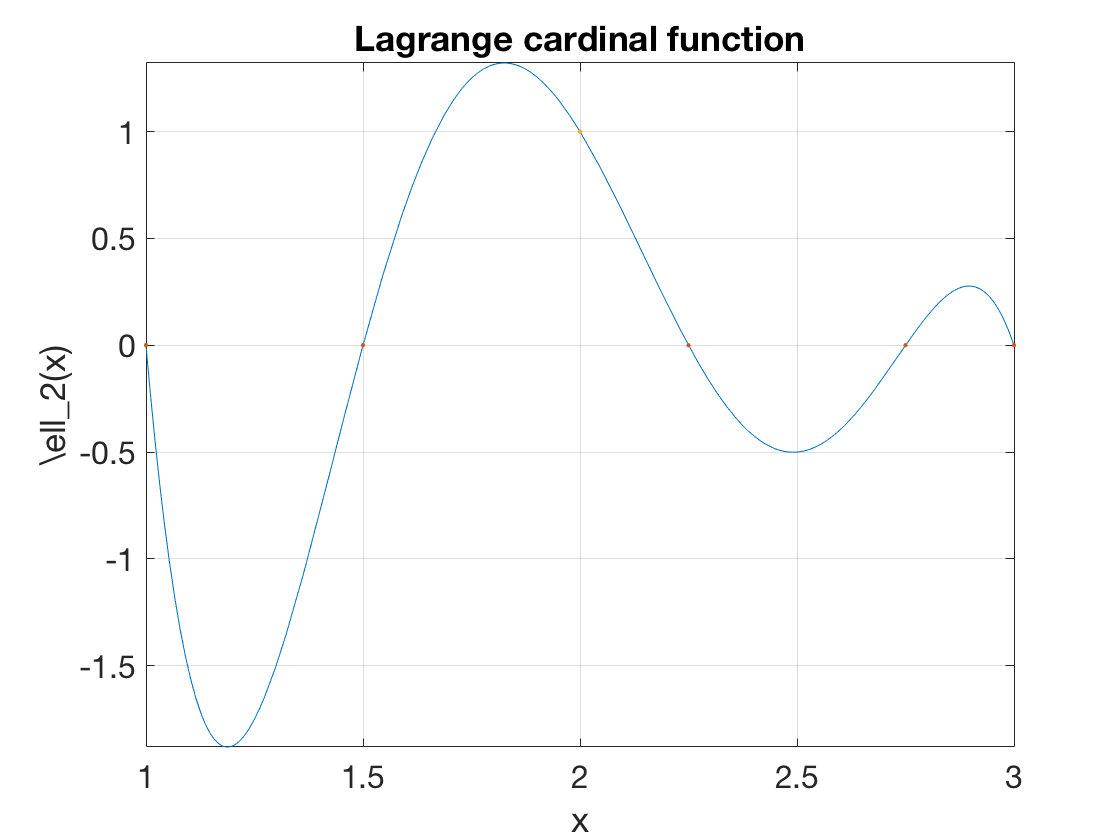

phi = @(x) prod(x-t(not_k+1));
ell_k = @(x) phi(x) ./ phi(t(k+1));

fplot(ell_k,[1 3])
hold on, grid on
plot(t(not_k+1),0*t(not_k+1),'.')
plot(t(k+1),1,'.')
xlabel('x'), ylabel('\ell_2(x)')    % ignore this line
title('Lagrange cardinal function')   % ignore this line

Observe that $\ell_k$ is *not* between zero and one everywhere between the nodes. 